% Definisco le matrici
A = [1, 4, 4;
     2, 2, 0;
     0, 0, -6]

A =      1     4     4
     2     2     0
     0     0    -6


B = [0; 0; 1]

B =      0
     0
     1


C = [4, 0, 0]

C =      4     0     0


D = 0

D = 0

% Definisco il sistema in orma di stato
sys_ol = ss(A,B,C,D)

sys_ol =
 
  A = 
       x1  x2  x3
   x1   1   4   4
   x2   2   2   0
   x3   0   0  -6
 
  B = 
       u1
   x1   0
   x2   0
   x3   1
 
  C = 
       x1  x2  x3
   y1   4   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.




% determino la f.d.t.
[n, d] = ss2tf(A,B,C,D)

n =      0     0    16   -32


d =      1     3   -24   -36


% Controllabilità ed Osservabilità
Mc=ctrb(A,B);
 if(rank(Mc)==length(A))
 disp("Il sistema è completamente controllabile")
 else
 disp("Il sistema non è completamente controllabile")
 end

Il sistema è completamente controllabile



 Mo=obsv(A,C);
 if(rank(Mo)==length(A))
 disp("Il sistema è completamente osservabile");
 else
 disp("Il sistema non è completamente osservabile");
 end

Il sistema è completamente osservabile


% Retroazione di Stato
p = [-1, -2, -3]

p =     -1    -2    -3


K = place(A,B,p)

K =    11.0000   18.5000    3.0000


% sistema chiuso in retroazione
sys_cl = ss(A-B*K,B,C,D)

sys_cl =
 
  A = 
          x1     x2     x3
   x1      1      4      4
   x2      2      2      0
   x3    -11  -18.5     -9
 
  B = 
       u1
   x1   0
   x2   0
   x3   1
 
  C = 
       x1  x2  x3
   y1   4   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



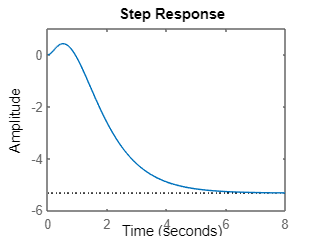


% risposta al gradino
step(sys_cl)


% verifico gli autovalori
eig(sys_cl)

ans =    -1.0000
   -2.0000
   -3.0000


% Osservatore di ordine ridotto
po = [-5, -30]

po =     -5   -30



Ad = A(2:3, 2:3)'

Ad =      2     0
     0    -6


Bd = (C(1)*A(1,2:3))'

Bd =     16
    16



kd = place(Ad,Bd,po)

kd =     1.7500    0.1875



%verifico gli autovalori
L = kd'

L =     1.7500
    0.1875


F = A(2:3,2:3) - L*C(1)*A(1,2:3)

F =   -26.0000  -28.0000
   -3.0000   -9.0000


eig(F)

ans =   -30.0000
   -5.0000
